%Pathfinder: send robots commands to follow path through testing field

## SETUP

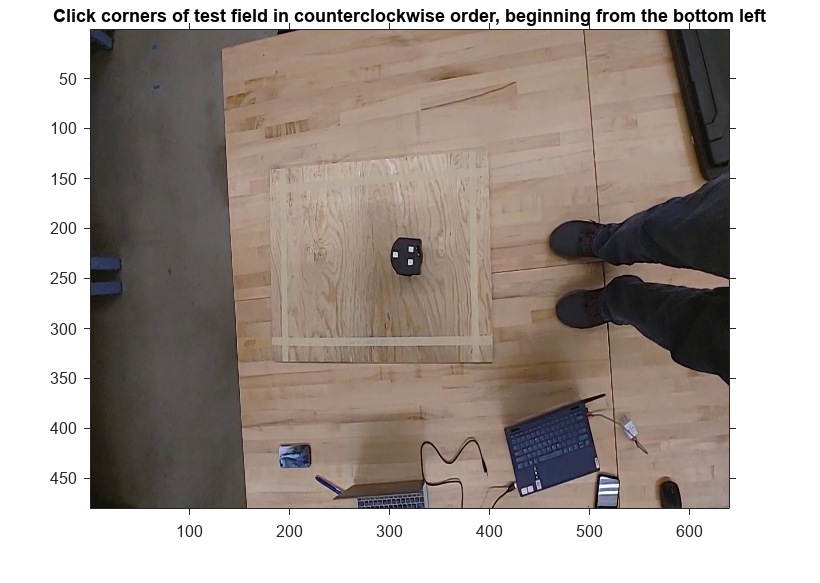

ImageConfiguration


% initialize environment settings
environment = Environment(1, bounds);

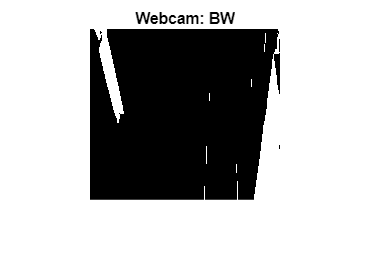

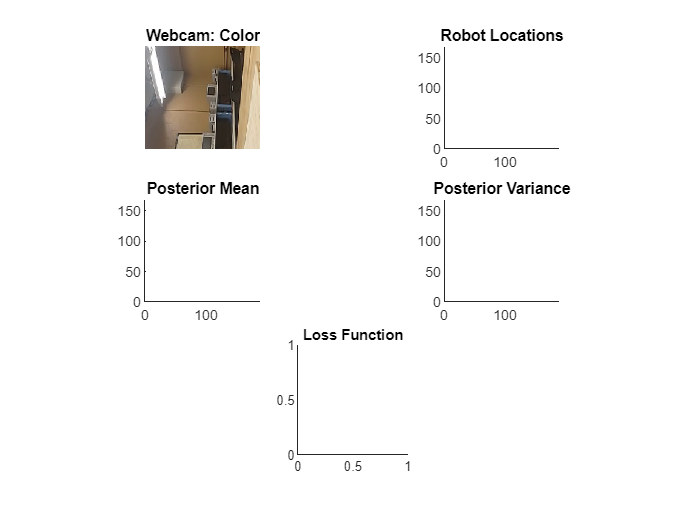

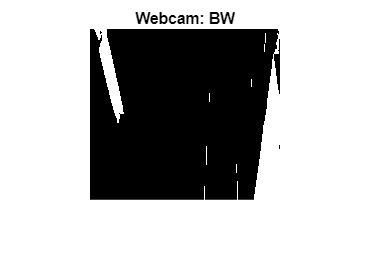


% initialize plot helper object
plotter = Plotter(environment);

% initialize webcam tracking and purge autofocus
vision = Vision(environment, plotter, transformation, bounds);


% initialize targets and navigation
navigator = Navigator(environment, plotter);
navigator = navigator.SetTargetsFromCSV('circle.csv');


% initialize communications
messenger = Messenger(environment, plotter);


hilgpc_data = HILGPC_Data;

Not enough input arguments.

Error in HILGPC_Data (line 86)
            obj.Environment = environment;

## ACTION

% initialize positions of robots in field
vision.UpdatePositions();

for i = 1:navigator.NumTargets

    % until robots are converged on this set of targets, get and send directions
    while(~navigator.IsConverged())

        % if positions up to date, get and send directions via UDP
        if vision.Updated
            
            directions = navigator.GetDirections();
            messenger.SendDirections(directions);

            % wait for directions to execute
            pause(environment.Delay);
        end
        
        % update positions
        vision.UpdatePositions();
        
        % update environment iteration tracker
        environment.Iterate();

    end
    
    % Repeat until robots all send back a valid sample
    while ~messenger.Received
        
        % send null directions to prompt robot feedback
        halt = navigator.GetHaltDirections();
        messenger.SendDirections(halt);
        
        % wait for directions to execute
        pause(environment.Delay);
        
        % read back feedback
        messenger.ReadMessage();
    end
    
    % Now, messenger.LastMessage contains an array of latest feedbacks
    samples = messenger.LastMessage;
    
    % Get positions for easy manipulation
    positions = hilgpc_data.PositionsToMatrix();
    
    % Update model with new samples
    hilgpc_data.UpdateModel(positions, samples);
    
    % move to next round of targets
    navigator.UpdateTargets();

end

% send halt command
halt = navigator.GetHaltDirections();
messenger.SendDirections(halt);

% Save recorded samples
samples_file = "../Data/collect_MFGP_2.csv";
hilgpc_data.SaveSamples(samples_file);